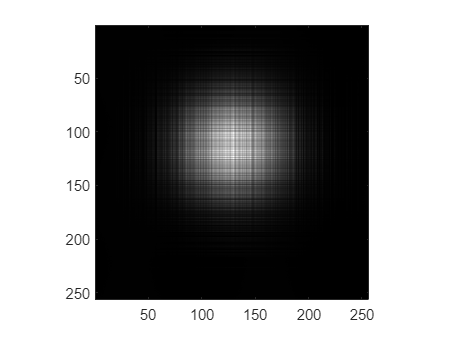

clear;

load("waves.mat");
ftwaves = fft2(waves);
imagesc(waves);

ORIGIM = imread('cameraman.tif');
ORIGIM = double(ORIGIM);
distance_map = zeros(size(ORIGIM,1), size(ORIGIM,1));
for n  = 1:size(ORIGIM,1)
 for m = 1:size(ORIGIM,2)
    distance_map(n,m) = manhattan(n, m, 9, 9);
 end
end
axis image;
colormap gray;

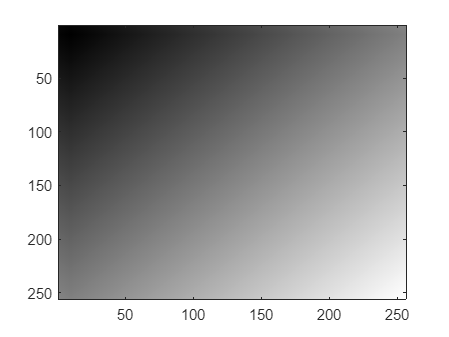

imagesc(distance_map);

k = 1;
mask = (distance_map <= k);

SFFTIMAGE = complex(zeros(size(ORIGIM)));
for k  = 1:16:size(ORIGIM,1)-15
 for m = 1:16:size(ORIGIM,2)-15
  SFFTIMAGE(k:k+15,m:m+15)=fftshift(fft2(ORIGIM(k:k+15,m:m+15)));
 end
end

for mthres = 1:max(mask(:))+1
 for k  = 1:16:size(ORIGIM,1)-15
  for m = 1:16:size(ORIGIM,2)-15
%   select the correct subimage from SFFTIMAGE   
%   mask, shift and inverse transform. Store result in  RECIMAGE
   RECIMAGE(k:k+15,m:m+15) = abs(RECIM);
  end
 end
 figure(1);imagesc(ORIGIM)
 figure(2);imagesc(RECIMAGE);
 drawnow
 pause
end

Unrecognized function or variable 'RECIM'.